% Membaca dataset
data = readtable('iris.data.csv');
input = table2array(data(:, 1:end-1)); % Asumsikan kolom terakhir adalah label
labels = data{:, end}; % Gunakan kurung kurawal untuk mengakses data dalam tabel

% Konversi label teks menjadi angka
uniqueLabels = unique(labels);
target = zeros(height(data), 1);
for i = 1:length(uniqueLabels)
    target(strcmp(labels, uniqueLabels{i})) = i;
end

% Normalisasi data
input = (input - min(input)) ./ (max(input) - min(input));

% Membagi dataset menjadi training dan testing dengan Stratified Sampling
ratio = 0.1;
uniqueTargets = unique(target);
trainIdx = [];
testIdx = [];

for i = 1:length(uniqueTargets)
    classIdx = find(target == uniqueTargets(i)); % Indeks dari kelas tertentu
    numTrainClass = round(ratio * length(classIdx));
    
    randClassIdx = randperm(length(classIdx));
    
    trainClassIdx = classIdx(randClassIdx(1:numTrainClass));
    testClassIdx = classIdx(randClassIdx(numTrainClass+1:end));
    
    trainIdx = [trainIdx; trainClassIdx];
    testIdx = [testIdx; testClassIdx];
end

inputTrain = input(trainIdx, :);
targetTrain = target(trainIdx);
inputTest = input(testIdx, :);
targetTest = target(testIdx);


% Inisialisasi
alpha = 0.4; %kecepatan learning
miu = 0.75; %momentum learning
n = size(inputTrain, 2); % Jumlah fitur
m1 = 10; % Jumlah neuron di hidden layer pertama
m2 = 10; % Jumlah neuron di hidden layer kedua
l = length(unique(targetTrain)); % Jumlah kelas
max_epoch = 10000;
EP = inf;

% Inisialisasi bobot dan bias dengan Nguyen-Widrow untuk hidden layer pertama
beta1 = 0.7 * m1^(1/n);
v1 = rand(n, m1) * 2 - 1;
normV1 = sqrt(sum(v1.^2));
v1 = beta1 * v1 ./ normV1;
v01 = (rand(1, m1) * 2 - 1) * beta1;

% Inisialisasi bobot dan bias untuk hidden layer kedua
v2 = rand(m1, m2) * 2 - 1;
v02 = rand(1, m2) * 2 - 1;

% Inisialisasi bobot dan bias untuk output layer
w = rand(m2, l) * 2 - 1;
w0 = rand(1, l) * 2 - 1;

%inisialiasi momentum perubahan bobot
deltaWPrev = zeros(size(w));
deltaV1Prev = zeros(size(v1));
deltaV2Prev = zeros(size(v2));
deltaW0Prev = zeros(size(w0));
deltaV01Prev = zeros(size(v01));
deltaV02Prev = zeros(size(v02));

epoch = 0;
previousEP = 0; %untuk kebutuhan grafik realtime
errorList = []; % Untuk menyimpan error pada setiap epoch
figure; % Membuka jendela figure untuk grafik

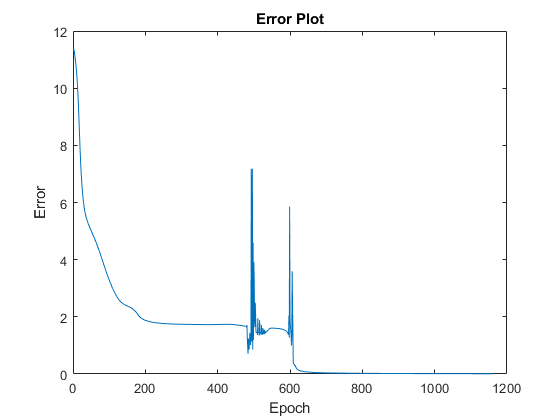


while EP > 0.01 && epoch < max_epoch
    EP = 0;
    for p = 1:size(inputTrain, 1)
        xi = inputTrain(p, :);
        tk = zeros(1, l);
        tk(targetTrain(p)) = 1;

        % Feedforward
        z1_in = zeros(1, m1);
        z1 = zeros(1, m1);
        for j = 1:m1
            z1_in(j) = xi * v1(:, j) + v01(j);
            z1(j) = 1 / (1 + exp(-z1_in(j)));
        end
        
        z2_in = zeros(1, m2);
        z2 = zeros(1, m2);
        for j = 1:m2
            z2_in(j) = z1 * v2(:, j) + v02(j);
            z2(j) = 1 / (1 + exp(-z2_in(j)));
        end
        
        y_in = zeros(1, l);
        y = zeros(1, l);
        for k = 1:l
            y_in(k) = z2 * w(:, k) + w0(k);
            y(k) = 1 / (1 + exp(-y_in(k)));
        end
        
        % Backpropagation
        delta_k = zeros(1, l);
        for k = 1:l
            delta_k(k) = (tk(k) - y(k)) * y(k) * (1 - y(k));
        end
        
        delta_j2 = zeros(1, m2);
        for j = 1:m2
            sum_delta_w = 0;
            for k = 1:l
                sum_delta_w = sum_delta_w + delta_k(k) * w(j, k);
            end
            delta_j2(j) = sum_delta_w * z2(j) * (1 - z2(j));
        end
        
        delta_j1 = zeros(1, m1);
        for j = 1:m1
            sum_delta_v = 0;
            for jj = 1:m2
                sum_delta_v = sum_delta_v + delta_j2(jj) * v2(j, jj);
            end
            delta_j1(j) = sum_delta_v * z1(j) * (1 - z1(j));
        end

        % Update bobot dan bias dengan momentum
        for k = 1:l
            for j = 1:m2
                deltaW = alpha * delta_k(k) * z2(j);
                w(j, k) = w(j, k) + deltaW + miu * deltaWPrev(j, k);
                deltaWPrev(j, k) = deltaW;
            end
            deltaW0 = alpha * delta_k(k);
            w0(k) = w0(k) + deltaW0 + miu * deltaW0Prev(k);
            deltaW0Prev(k) = deltaW0;
        end
        
        for j = 1:m2
            for jj = 1:m1
                deltaV2 = alpha * delta_j2(j) * z1(jj);
                v2(jj, j) = v2(jj, j) + deltaV2 + miu * deltaV2Prev(jj, j);
                deltaV2Prev(jj, j) = deltaV2;
            end
            deltaV02 = alpha * delta_j2(j);
            v02(j) = v02(j) + deltaV02 + miu * deltaV02Prev(j);
            deltaV02Prev(j) = deltaV02;
        end
        
        for j = 1:m1
            for i = 1:n
                deltaV1 = alpha * delta_j1(j) * xi(i);
                v1(i, j) = v1(i, j) + deltaV1 + miu * deltaV1Prev(i, j);
                deltaV1Prev(i, j) = deltaV1;
            end
            deltaV01 = alpha * delta_j1(j);
            v01(j) = v01(j) + deltaV01 + miu * deltaV01Prev(j);
            deltaV01Prev(j) = deltaV01;
        end
        
        EP = EP + sum((tk - y).^2);
    end
    
    % Plotting error setiap epoch
    errorList = [errorList EP];
    plot(errorList);
    title('Error Plot');
    xlabel('Epoch');
    ylabel('Error');
    drawnow;
    
    epoch = epoch + 1;
end


% Menyimpan bobot dan bias ke dalam file Excel
filename = 'weights_biases.xlsx';

% Menyimpan bobot dari input ke hidden layer pertama dengan label
labels_v1 = cell(size(v1));
for i = 1:size(v1, 1)
    for j = 1:size(v1, 2)
        labels_v1{i, j} = strcat('InputNode', num2str(i), '_to_HiddenLayer1Node', num2str(j));
    end
end
xlswrite(filename, labels_v1, 'Sheet1', 'A1');
xlswrite(filename, v1, 'Sheet1', 'B1');

% Menyimpan bias dari hidden layer pertama
xlswrite(filename, {'Bias_for_HiddenLayer1'}, 'Sheet1', strcat('A', num2str(size(v1,1) + 2)));
xlswrite(filename, v01, 'Sheet1', strcat('B', num2str(size(v1,1) + 2)));

% Menyimpan bobot dari hidden layer pertama ke hidden layer kedua dengan label
labels_v2 = cell(size(v2));
for i = 1:size(v2, 1)
    for j = 1:size(v2, 2)
        labels_v2{i, j} = strcat('HiddenLayer1Node', num2str(i), '_to_HiddenLayer2Node', num2str(j));
    end
end
xlswrite(filename, labels_v2, 'Sheet2', 'A1');
xlswrite(filename, v2, 'Sheet2', 'B1');

% Menyimpan bias dari hidden layer kedua
xlswrite(filename, {'Bias_for_HiddenLayer2'}, 'Sheet2', strcat('A', num2str(size(v2,1) + 2)));
xlswrite(filename, v02, 'Sheet2', strcat('B', num2str(size(v2,1) + 2)));

% Menyimpan bobot dari hidden layer kedua ke output layer dengan label
labels_w = cell(size(w));
for i = 1:size(w, 1)
    for j = 1:size(w, 2)
        labels_w{i, j} = strcat('HiddenLayer2Node', num2str(i), '_to_OutputNode', num2str(j));
    end
end
xlswrite(filename, labels_w, 'Sheet3', 'A1');
xlswrite(filename, w, 'Sheet3', 'B1');

% Menyimpan bias dari output layer
xlswrite(filename, {'Bias_for_OutputLayer'}, 'Sheet3', strcat('A', num2str(size(w,1) + 2)));
xlswrite(filename, w0, 'Sheet3', strcat('B', num2str(size(w,1) + 2)));



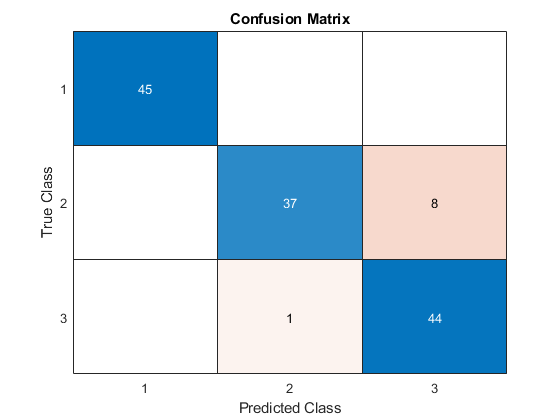


% Evaluasi pada dataset testing
correct = 0;
predictedLabels = zeros(size(inputTest, 1), 1);

for p = 1:size(inputTest, 1)
    xi = inputTest(p, :);
    tk = zeros(1, l);
    tk(targetTest(p)) = 1;

    % Feedforward untuk hidden layer pertama
    z1_in = v01 + xi * v1;
    z1 = 1 ./ (1 + exp(-z1_in));

    % Feedforward untuk hidden layer kedua
    z2_in = v02 + z1 * v2;
    z2 = 1 ./ (1 + exp(-z2_in));

    % Feedforward untuk output layer
    y_in = w0 + z2 * w;
    y = 1 ./ (1 + exp(-y_in));

    [~, predicted] = max(y);
    predictedLabels(p) = predicted;
    if predicted == targetTest(p)
        correct = correct + 1;
    end
end

figure; % Membuka jendela figure baru
confusionchart(targetTest, predictedLabels);
title('Confusion Matrix');

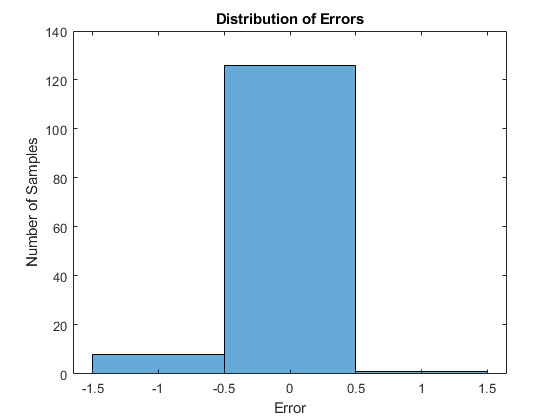


% Visualisasi Kesalahan
errors = targetTest - predictedLabels;
figure; % Membuka jendela figure baru
histogram(errors);
title('Distribution of Errors');
xlabel('Error');
ylabel('Number of Samples');


accuracy = correct / size(inputTest, 1) * 100;
disp(['Akurasi pada dataset testing: ' num2str(accuracy) '%']);

Akurasi pada dataset testing: 93.3333%
